# **DSP Lab 8**

## **Syed Asghar Abbas Zaidi and Samiya Ali Zaidi**

### **Spring 2024**

## **Solving inverse Z-transform using transform**

## **Task 1 (warm-up)**


$$\mathcal{Z}^{-1} \left\{ \frac{2z}{2z - 1} \right\}
$$


% Define symbolic variables z and n
syms z n

% Compute the inverse Z-transform of the expression (2*z / (2*z - 1))
iztrans(2*z / (2*z - 1))

$$ans = {\left(\frac{1}{2}\right)}^{n}$$

### Analysing the result: 

The code computes the inverse Z-transform of the expression (2z/2z-1)�, resulting in the sequence (1/2)^n. This sequence represents a geometric sequence where each term decays exponentially as *n* increases.

## Problem 1: 

### ***Compute inverse Z-transform***


$$\frac{1}{{\left(1-0\ldotp {9z}^{-1} \right)}^2 \left(1+0\ldotp 9z^{-1} \right)},|z|>0\ldotp 9$$


% Define symbolic variables z and n
%syms z n

% Compute the inverse Z-transform of the expression
exp = 1/((1-0.9*(z^-1 ))*(1-0.9*(z^-1))*(1+0.9*(z^-1)));
disp('Expression:');

Expression:


disp(exp);

$$\frac{1}{{\left(\frac{9}{10\,z}-1\right)}^{2}\,\left(\frac{9}{10\,z}+1\right)}$$

inv_exp = iztrans(exp);
disp(inv_exp);

$$\frac{{\left(-\frac{9}{10}\right)}^{n}}{4}+\frac{5\,{\left(\frac{9}{10}\right)}^{n}}{4}+\frac{{\left(\frac{9}{10}\right)}^{n}\,\left(n-1\right)}{2}$$

%b = [1];
%a = poly([0.9 0.9 -0.9])
%a = [0.729 -0.81 -0.9 1];
%[r,p,c] = residuez(b,a)
%disp("Following ")

## ***Task 2 Problem 1  ***

### Determine the inverse z-transform of


$$\frac{1+0\ldotp 4\;\sqrt{2}z^{-1} \;\;}{1-0\ldotp 8\sqrt{2}z^{-1} +0\ldotp 64z^{-2} }$$


syms z n
num2 = 1+(0.4)*(z^-1)*((2)^(1/2));
dem2 = (1)-(0.8)*((2)^(1/2))*(z^-1)+((0.64)*(z^-2));
exp2 = num2/dem2;
disp(exp2);

$$\frac{\frac{2\,\sqrt{2}}{5\,z}+1}{\frac{16}{25\,z^{2}}-\frac{4\,\sqrt{2}}{5\,z}+1}$$

inv_exp2 = iztrans(exp2);   
disp(inv_exp2);

$$\frac{3\,{\left(-1\right)}^{n}\,16^{n}\,\cos\left(\frac{3\,\pi \,n}{4}\right)}{20^{n}}+\frac{4\,{\left(-1\right)}^{n}\,\sqrt{2}\,25^{1-n}\,{\left(\sqrt{2}\,\left(-10-10\,\mathrm{i}\right)\right)}^{n-1}\,\mathrm{i}}{5}-\frac{4\,{\left(-1\right)}^{n}\,\sqrt{2}\,25^{1-n}\,{\left(\sqrt{2}\,\left(-10+10\,\mathrm{i}\right)\right)}^{n-1}\,\mathrm{i}}{5}$$

### **run abs(p) and angle(p)!**

Mp=(abs(p)) % pole magnitudes 

Mp =     0.8000
    0.8000


Ap=(angle(p))/pi % pole angles in pi units

Ap =     0.2500
   -0.2500


### **Questions: **

#### a) What is R P C? 

**Residues (R)**: These are coefficients associated with the terms in a partial fraction expansion, providing insights into a system's response to different frequencies or inputs.

**Poles (P)**: These are critical points where a system's transfer function becomes infinite or undefined, influencing stability, transient response, and frequency response characteristics.

**Coefficients (C)**: These represent the constants or scaling factors in a system's mathematical representation, determining its dynamic behavior and response to inputs.

numerator = [1, 0.4*sqrt(2)];
denominator = [1, -0.8*sqrt(2), 0.64];
[R, p, C] = residuez (numerator, denominator)

R =    0.5000 - 1.0000i
   0.5000 + 1.0000i


p =    0.5657 + 0.5657i
   0.5657 - 0.5657i



C =

     []



#### Analysis: 

The output consists of complex numbers representing residues and poles. Residues (𝑅*R*) indicate how the system responds to different inputs, while poles (𝑝*p*) denote critical points influencing stability and frequency response. The complex nature of residues and poles suggests complex frequency response characteristics. Complex poles indicate oscillatory or damped behavior, while complex residues reveal frequency-dependent amplification or attenuation.

#### b) What is Mp and Ap?

- **Mp**: Magnitudes of poles. It represents the absolute values of the poles in a row vector format.

- **Ap**: Pole angles in units of *π*. It represents the angles of the poles in radians, converted to units of *π* in a row vector format.

### Task 3 (Warmup)

% syms z n
% E_num = 2*z;
% E_dem = 2*z-1;
% E = E_num/E_dem
% E_inv = iztrans(2*z/(2*z-1))
% zplane(sym2poly(E_num), sym2poly(E_dem));
% root(E_num)
% root(E_dem)

n=[1 -1.6180 1];         % same as bs in Difference Eqn. model
d=[1 -1.5161 0.878];   % same as as in Difference Eqn. model
roots(d) 		 % Poles of the function

ans =    0.7581 + 0.5508i
   0.7581 - 0.5508i


roots(n)		% Zeroes of the function

ans =    0.8090 + 0.5878i
   0.8090 - 0.5878i


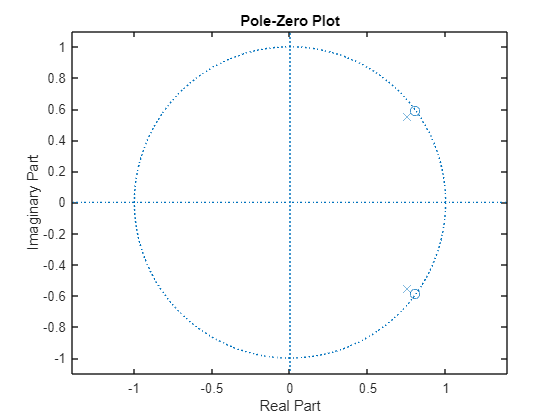

zplane(n,d)	% generates pole-zero diagram of the function

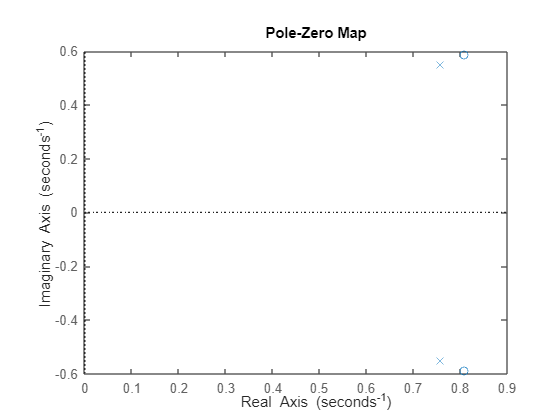

pzmap(n,d)

The `pzmap` function also generates a pole-zero plot similar to `zplane`, providing another way to visualize the poles and zeros of the transfer function.

### What does following command do. Add comments to the code, and discuss the result. What does SOS command do?

#### tf2zpk!

[z,p,k]=tf2zpk(n,d)

z =    0.8090 + 0.5878i
   0.8090 - 0.5878i


p =    0.7581 + 0.5508i
   0.7581 - 0.5508i


k = 1

The MATLAB function `tf2zpk` is used to convert a transfer function representation from its polynomial coefficient form to its zero-pole-gain (ZPK) form. Each output variant represents:

- `z`: Zeros of the transfer function.

- `p`: Poles of the transfer function.

- `k`: The system gain or overall scaling factor of the transfer function.

This function is useful for analyzing and visualizing the characteristics of the transfer function, such as the location of zeros and poles in the complex plane, and the overall gain of the system.

### zp2sos!

[sos k]= zp2sos(z,p,k)

sos =     1.0000   -1.6180    1.0000    1.0000   -1.5161    0.8780


k = 1

The `zp2sos` function converts the zeros and poles of the transfer function into second-order sections (SOS) representation. The variable `k` represents the gain factor of the transfer function.

zplane(z,p)

### Analysis:

Output describes a system with complex poles and zeros**, suggesting oscillatory behavior or resonance in its frequency response.** The** gain factor is unity,** and the **system is represented in terms of second-order sections, which can be useful for implementing the system in digital filter designs or signal processing applications.**

# Post-lab Exercise

## Question 1

### Find the inverse z-transform of the following transfer function


$$Y(z) = \frac{1}{(1+z^{-1})(1-z^{-1})^2}$$


syms z n

% transfer function Y(z)
Y_z = 1 / ((1 + z^(-1)) * (1 - z^(-1))^2);


% inverse z-transform of the transfer function
y_n = iztrans(Y_z, z, n);

% result
disp('Inverse Z-transform of Y(z):');

Inverse Z-transform of Y(z):


disp(y_n)

$$\frac{n}{2}+\frac{{\left(-1\right)}^{n}}{4}+\frac{3}{4}$$

## Question 2

### Find out the inverse z – Transform of the following function?


$$X(z) = \frac{6 - 9z^{-1}}{1 - 2.5z^{-1} + z^{-2}}$$


clear all

syms z n

% transfer function
X_z = (6 - 9*z^(-1))/(1 - 2.5*z^(-1) + z^(-2));

% inverse z-transform of the transfer function
x_n = iztrans(X_z, z, n);

% result
disp('Inverse Z-transform of Y(z):');

Inverse Z-transform of Y(z):


disp(x_n)

$$2\,2^{n}+4\,{\left(\frac{1}{2}\right)}^{n}$$

## Question 3

### Determine the Z-transform of $x[n] = 10\cos{2n}$

clear all

syms z n 

% Define the signal x[n]
x_n = 10 * cos(2 * n);

% Compute the Z-transform of x[n]
X_z = ztrans(x_n, n, z);

% Display the result
disp('z-transform of x[n]:');

z-transform of x[n]:


disp(X_z)

$$\frac{10\,z\,\left(z-\cos\left(2\right)\right)}{z^{2}-2\,\cos\left(2\right)\,z+1}$$

## Question 4

### Given is the system function of a DT LTI system. Also Find z p k using "`SoS = zp2sos(z, p, k)"`

num = [2 4 8 5 2];
den = [2 36 3 2 1];

[z, p, k] = tf2zpk(num, den);
[sos, k]= zp2sos(z, p, k)

sos =     1.0000    1.2413    2.6859    1.0000   18.1869    4.7953
    1.0000    0.7587    0.3723    1.0000   -0.1869    0.1043


k = 1

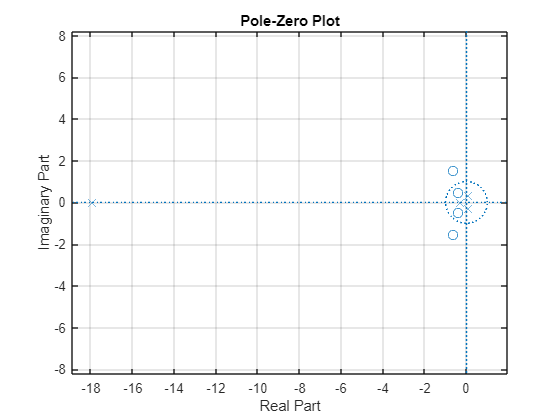

zplane(z, p);
grid on

### What does SOS represent?

**SOS** stands for **second-order sections. **It is a way to represent the transfer function of a system in a more numerically stable way by reducing the chances of overflow and underflow, especially for complex higher order filters. SOS splits the transfer function into multiple section with their own numerators and denominators to simplify the calculations.

## Question 5

### Plot the zero-pole diagram for: 


$$X(z) = \frac{1}{(1- 0.9z^{-1})^2(1 + 0.9z^{-1})}$$


clear all

To make the pole-zero plot, the transfer function should be represented using the coefficients of powers of z. For this, I had to simplify the denominator first. The new equation was:


$$X(z) = \frac{1}{1 - 0.9z^{-1} - 0.81z^{-2} + 0.729z^{-3}}$$


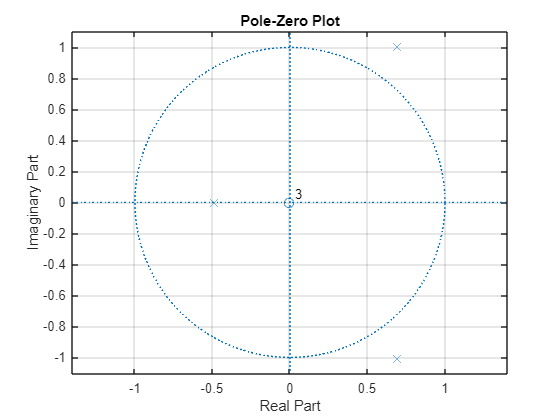

num = [1, 0, 0, 0];
den = [1, -0.9, 0.81, 0.729];

zplane(num, den);
grid on;

The system is unstable because there are two poles outside of the unit circle.

## Question 6

### A causal, linear, and time-invariant system is given by the following difference equation: 

### 
$$y[n] = y[n-1] + y[n-2] +x[n-1]$$


### Find the system function H (z) for this system. 

#### 
$$Y(z) = z^{-1}Y(z) + z^{-2}Y(z) + z^{-1}X(z)
\\
Y(z) [1 -z^{-1} -z^{-2}] = z^{-1}X(z)
\\
H(z) = \frac{z^{-1}}{1 -z^{-1} -z^{-2}}$$


### Plot the poles and zeros of H (z) and indicate the region of convergence (ROC). 

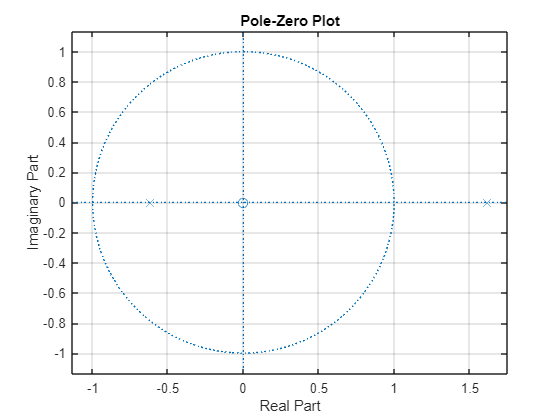

clear all

num = [0, 1, 0];
den = [1, -1, -1];

zplane(num, den);
grid on

[R, p, C] = residuez(num, den)

R =     0.4472
   -0.4472


p =     1.6180
   -0.6180


C = 0

The ROC is $|z|>1.6180$. This was found by looking at the maximum absolute value of the pole's location. This also means that the system is not stable because the ROC does not include the unit circle.

### Find the unit sample response h (n) of this system. 

**Inverse z-Transform**

clear all

syms z n

% the system funtion
H_z = (z^(-1))/(1 - z^(-1) - z^(-2));

% compute the inverse z transform
h_n = iztrans(H_z, z, n);

% Display the result
disp('Inverse z-transform of H(z):');

Inverse z-transform of H(z):


disp(h_n)

$$\begin{array}{l} \frac{2\,{\left(-1\right)}^{n}\,\cos\left(n\,\left(\frac{\pi }{2}+\mathrm{asin}\left(\frac{1}{2}\,\mathrm{i}\right)\right)\right)}{{\mathrm{i}}^{n}}-\frac{2\,\sigma_{1}\,{\left(-1\right)}^{n}\,\sqrt{5}\,{\left(\frac{1}{2}-\frac{\sqrt{5}}{2}\right)}^{n-1}}{5}+\frac{2\,\sigma_{1}\,{\left(-1\right)}^{n}\,\sqrt{5}\,{\left(\frac{\sqrt{5}}{2}+\frac{1}{2}\right)}^{n-1}}{5}\\ \mathrm{where}\\ \sigma_{1}={\left(-1\right)}^{1-n} \end{array}$$